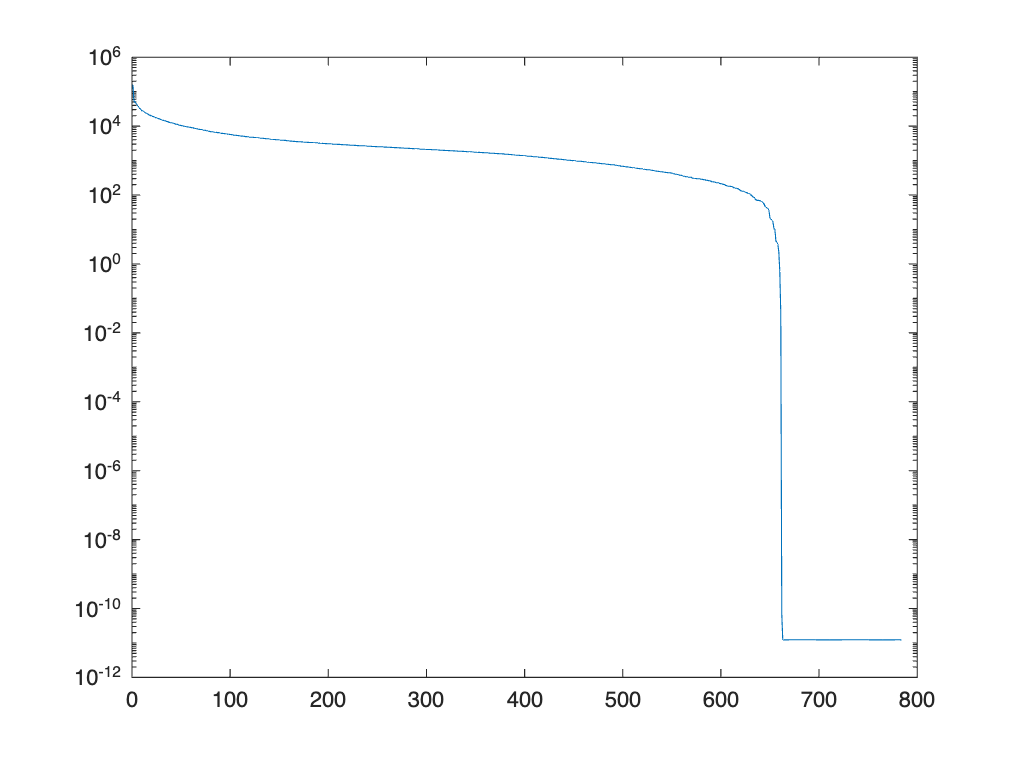

clear all
clc
SetRNG(111);
warning("off")
load ('mnist.mat')
colormap(gray(256))
images = rescale(test.images(:,:,:),0,255);
data = reshape(images,784,10000);
% tree = linkage(data');
% dendrogram(tree,200)
%data = data - mean(data,1);
[U, S, V] = svd(data, 'econ');
diag(S);
semilogy(diag(S))

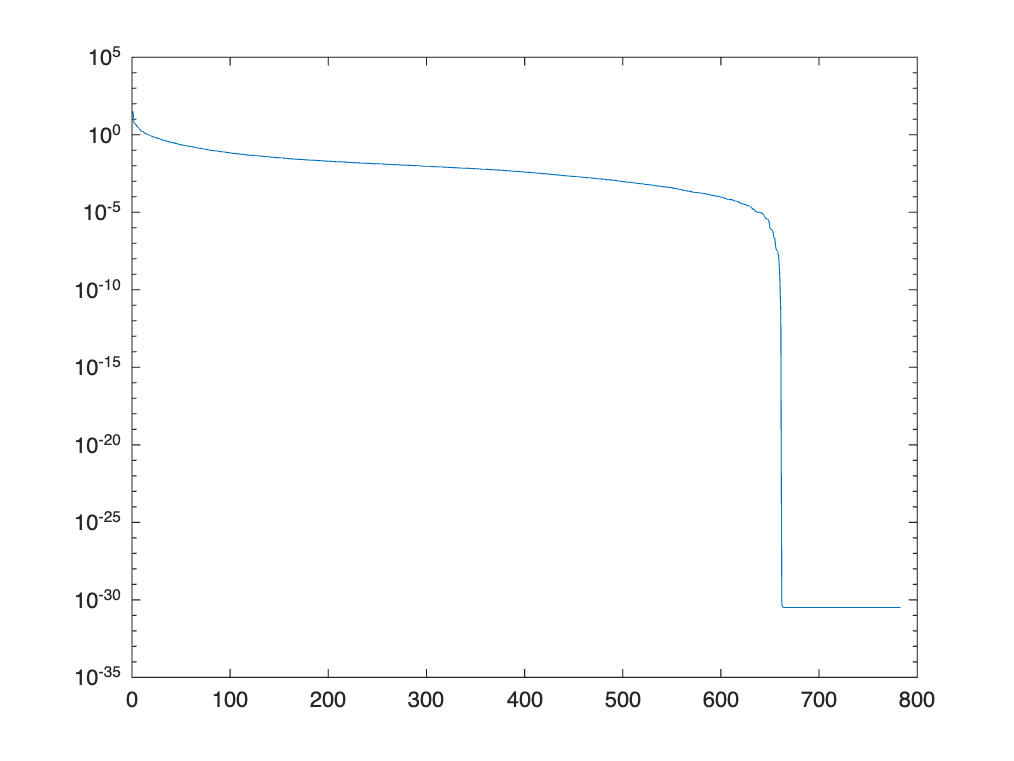

[coeff, score, latent, ~, explained_pca] = pca(data); 
semilogy(explained_pca)

% cycle 1
K = 11;
assign_id = test.labels;
[idx,C,sumd,D] = kmeans(data',11,'Distance','cosine');
DHC_assignment = [assign_id,idx];
[M,N] = groupcounts(idx);
PTY1_before = purity(idx,assign_id)
NMI1_before = nmi(assign_id, idx)
[RI1_before, ARI1_before] = randindex(assign_id, idx)
[s1_before] = ClusterEvalSilhouette (data', idx, 'cosine')
ch1_before = ClusterEvalCalinskiHarabasz(data', idx)
[db1_before] = ClusterEvalDaviesBouldin (data', idx)

%before merge
figure;
cycle1_centroids_nomerge = [];
for k = 1:12
    if k > K;
        break
    end
    data_idx = find(idx == k);
    images = data(:,data_idx)';
    images = mean(images,1);
    cycle1_centroids_nomerge = [cycle1_centroids_nomerge,images'];
    subplot(4,3,k)
    colormap(gray(256))
    image(reshape(images,28,28));
    set(gca,'XTick',[], 'YTick', [])
    %pause(0.2);
end

sub_divide = [];
for k = 1:K;
    data_idx = find(idx == k);
    CSL_check = DHC_assignment(data_idx,1);
    num_max_class = numel(find(CSL_check==mode(CSL_check)));

    if length(unique(CSL_check)) == 1 | num_max_class/length(CSL_check) >= 0.7;
        disp('cluster with centroid index '+string(k)+' is not subdivisible')
    else
        disp('cluster with centroid index '+string(k)+' is subdivisible')
        sub_divide = [sub_divide;k];
    end
end

% manually check merge
% k = 2;
% cycle_1_center = cycle1_centroids_nomerge(:,k);
% figure;
% colormap(gray(256))
% image(reshape(cycle_1_center,28,28))
% 
% labels = assign_id(find(idx == k));
% [GC,GR] = groupcounts(labels); 
% [GC,GR]


%after merge
for_merging = {[1;7],[4;11]};
cycle1_assignment_merge = idx;
for i=1:length(for_merging);
    merge_id = cell2mat(for_merging(i));
    [Lia,Locb] = ismember(idx,merge_id);
    merge_data_idx = find(Lia==1);
    cycle1_assignment_merge(merge_data_idx) = merge_id(1); %any new name
end 

% merge_id = [1;7];
% [Lia,Locb] = ismember(idx,merge_id);
% merge_data_idx = find(Lia==1);
% cycle1_assignment_merge(merge_data_idx) = merge_id(1); %any new name

unique_assignment_merge = unique(cycle1_assignment_merge);
cycle1_centroids_merge = [];
figure;
for k = 1:length(unique_assignment_merge)
    data_idx = find(cycle1_assignment_merge == unique_assignment_merge(k));
    images = data(:,data_idx)';
    images = mean(images,1);
    cycle1_centroids_merge = [cycle1_centroids_merge,images'];
    subplot(4,3,k)
    colormap(gray(256))
    image(reshape(images,28,28));
    set(gca,'XTick',[], 'YTick', [])
    %pause(0.2);
end

sub_divide = [];
for k = 1:length(unique_assignment_merge)
    data_idx = find(cycle1_assignment_merge == unique_assignment_merge(k));
    CSL_check = assign_id(data_idx);
    num_max_class = numel(find(CSL_check==mode(CSL_check)));

    if length(unique(CSL_check)) == 1 | num_max_class/length(CSL_check) >= 0.7;
        disp('cluster with centroid index '+string(unique_assignment_merge(k))+' is not subdivisible')
    else
        disp('cluster with centroid index '+string(unique_assignment_merge(k))+' is subdivisible')
        sub_divide = [sub_divide;unique_assignment_merge(k)];
    end
end

[Lia,Locb] = ismember(cycle1_assignment_merge,sub_divide);
sub_divide_data_idx = find(Lia==1);



PTY1_after = purity(cycle1_assignment_merge,assign_id)
NMI1_after = nmi(assign_id, cycle1_assignment_merge)
[RI1_after, ARI1_after] = randindex(assign_id, cycle1_assignment_merge)
[s1_after] = ClusterEvalSilhouette (data', cycle1_assignment_merge, 'cosine')
ch1_after = ClusterEvalCalinskiHarabasz(data', cycle1_assignment_merge)
[db1_after] = ClusterEvalDaviesBouldin (data', cycle1_assignment_merge)

% c2_DHC = {};
% k2 = 2;
% c2_center = sub_divide(k2);
% data_idx = find(cycle1_assignment_merge == c2_center);
% K = sum(groupcounts(assign_id(data_idx))>20);
% [a,b] = groupcounts(assign_id(data_idx));
% [a,b]

sub_divide_assign = cycle1_assignment_merge;
c2_DHC = {};
for k2 = 1:length(sub_divide);
    c2_center = sub_divide(k2);
    data_idx = find(cycle1_assignment_merge == c2_center);
    K = sum(groupcounts(assign_id(data_idx))>20); 
    sub_data = data(:,data_idx)'; 
    [idx_2,C,sumd,D] = kmeans(sub_data,K,'Distance','cosine');
    sub_divide_assign(data_idx) = idx_2+k2*20;
    c2_DHC{k2} = [data_idx,idx_2+k2*20];
end


idx_2 = c2_DHC{1};
DHC2 = unique(idx_2(:,2));
% [m,n] = groupcounts(idx_2(:,2));
% [m,n]
figure;
for k = 1:length(unique(idx_2(:,2)))
    k_idx = find(idx_2(:,2) == DHC2(k));
    sub_data = data(:,idx_2(:,1))';
    images = sub_data(k_idx,:);
    images = mean(images,1);
    subplot(4,3,k)
    colormap(gray(256))
    image(reshape(images,28,28));
    set(gca,'XTick',[], 'YTick', [])
    %pause(0.2);
end


idx_2 = c2_DHC{2};
DHC2 = unique(idx_2(:,2));
figure;
for k = 1:length(unique(idx_2(:,2)))
    k_idx = find(idx_2(:,2) == DHC2(k));
    sub_data = data(:,idx_2(:,1))';
    images = sub_data(k_idx,:);
    images = mean(images,1);
    subplot(4,3,k)
    colormap(gray(256))
    image(reshape(images,28,28));
    set(gca,'XTick',[], 'YTick', [])
    %pause(0.2);
end

idx_2 = c2_DHC{3};
DHC2 = unique(idx_2(:,2));
figure;
for k = 1:length(unique(idx_2(:,2)))
    k_idx = find(idx_2(:,2) == DHC2(k));
    sub_data = data(:,idx_2(:,1))';
    images = sub_data(k_idx,:);
    images = mean(images,1);
    subplot(4,3,k)
    colormap(gray(256))
    image(reshape(images,28,28));
    set(gca,'XTick',[], 'YTick', [])
    %pause(0.2);
end


PTY2_after = purity(sub_divide_assign,assign_id)
NMI2_after = nmi(assign_id, sub_divide_assign)
[RI2_after, ARI2_after] = randindex(assign_id, sub_divide_assign)
[s2_after] = ClusterEvalSilhouette (data', sub_divide_assign, 'cosine')
ch2_after = ClusterEvalCalinskiHarabasz(data', sub_divide_assign)
[db2_after] = ClusterEvalDaviesBouldin (data', sub_divide_assign)

% cycle3_assignment = {};
% for i = 1:length(c2_DHC);
%     sub_DHC = c2_DHC{i};
%     [m,n] = groupcounts(sub_DHC(:,2));
%     cycle3_assignment{i} = [n,m];
% end
% 
% MNIST_DHC_MERGE_DEN.clustAssignments = cycle1_assignment_merge;
% MNIST_DHC_MERGE_DEN.cycle3_assignment = cycle3_assignment;
% MNIST_DHC_MERGE_DEN.sub_divide_assign = sub_divide_assign;
% MNIST_DHC_MERGE_DEN.subdivi_winner_idx = sub_divide;
% MNIST_DHC_MERGE_DEN.X = data;
% save("MNIST_DHC_MERGE_DEN.mat","-struct","MNIST_DHC_MERGE_DEN")